clc;
close all
fc=input("enter the fq in MHZ");
hte = input("enter transmitting antenna height in m: ");
hre = input("enter receiving antenna height in m: ");
%d=input("t-r seperation distance in km");
d=(100:1000);
disp("select area type")

select area type


disp("1.urban area")

1.urban area


disp("2.suburban area")

2.suburban area


disp("3.rural area")

3.rural area


1.small city


2.large city


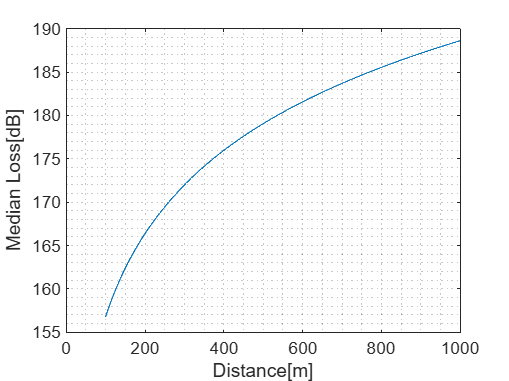

choice=input("enter your area type in numeric type");
if choice==1
   disp("1.small city")
   disp("2.large city")
   choice1 = input("Enter the city type :- ");
   if choice1==1
       ahre = (((1.1*log10(fc)-0.7)*hre)-((1.5*log10(fc)-0.8)));
       L50_urban = ((69.55+26.16*log10(fc))-(13.82*log10(hte))-(ahre)+((44.9-6.55*log10(hte))*log10(d)));
       plot(d,L50_urban);
       xlabel("Distance[m]");
       ylabel("Median Loss[dB]");
       grid minor
   end
   if choice1==2
       ahre = (8.29*((log(1.54*hre))^2-1.1));
       L50_urban = ((69.55+26.16*log10(fc))-(13.82*log10(hte))-(ahre)+((44.9-6.55*log10(hte))*log10(d)));
       plot(d,L50_urban);
       xlabel("Distance[m]");
       ylabel("Median Loss[dB]");
       grid minor
   end
end

if choice==2
    disp("1.small city")
    disp("2.large city")
    choice1 = input("Enter the city type :- ");
    if choice1==1
        ahre = (((1.1*log(fc)-0.7)*hre)-((1.56*log(fc)-0.8)));
        L50_urban = ((69.55+26.16*log10(fc))-(13.82*log10(hte))-(ahre)+((44.9-6.55*log10(hte))*log10(d)));
        plot(d,L50);
        xlabel("Distance[m]");
        ylabel("Median Losses[dB]");
        grid minor
    end
         
    if choice1==2
        ahre = 8.29*(log(1.54*hre))^2-1.1;
        L50_urban = ((69.55+26.16*log10(fc))-(13.82*log10(hte))-(ahre)+((44.9-6.55*log10(hte))*log10(d)));
        plot(d,L50_urban);
        xlabel("Distance[m]");
        ylabel("Median Loss[dB]");
        grid minor
    end
end
if choice==3
    disp("1.small city")
    disp("2.large city")
    choice1 = input("Enter the city type :- ");
    if choice1==1
        ahre = (((1.1*log10(fc)-0.7)*hre)-((1.56*log10(fc)-0.8)));
        L50_urban = ((69.55+26.16*log10(fc))-(13.82*log10(hte))-(ahre)+((44.9-6.55*log10(hte))*log10(d)));
        plot(d,L50_urban);
        xlabel("Distance[m]");
        ylabel("Median Loss[dB]");
        grid minor;
    end
    if choice1==2
        ahre = (8.29*((log10(1.54*hre))^2-1.1));
        L50_urban = ((69.55+26.16*log10(fc))-(13.82*log10(hte))-(ahre)+((44.9-6.55*log10(hte))*log10(d)));
        plot(d,L50_urban);
        xlabel("Distance[m]");
        ylabel("Median Loss[dB]");
        grid minor;
    end
    L50 = L50_urban-((4.78*((log10(fc)^2))-((18.33*log10(fc))-40.98)));
end